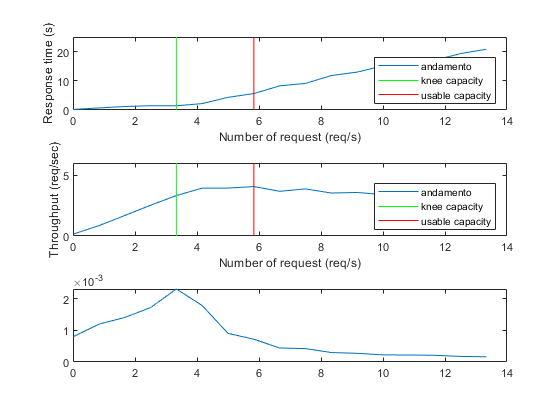

clear
load = (0:50:800)./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity misto\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity misto\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{8});
    throughput(i) = str2double(strrep(C{8}{8},',','.'));
    fclose(fileID);
end
power = throughput./response_time;
subplot(3,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 25000].*0.001,'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 25000].*0.001,'Color','red');
legend('andamento','knee capacity','usable capacity','Location','southeast')
subplot(3,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 6],'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 6],'Color','red');
legend('andamento','knee capacity','usable capacity','Location','southeast')
subplot(3,1,3);
plot(load, power)
saveas(gcf,'capacity_misto','png');

clf

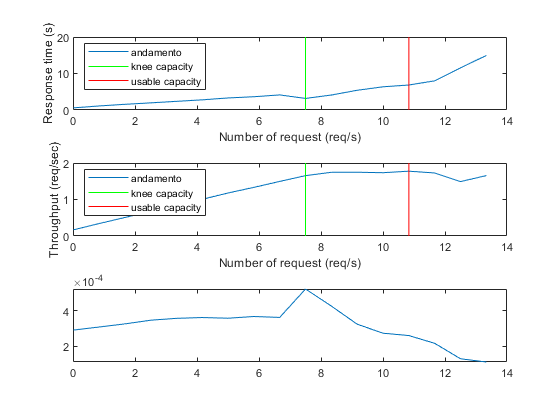

clear
load = (0:50:800)./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity big\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity big\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
power = throughput./response_time;
subplot(3,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 20000].*0.001,'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 20000].*0.001,'Color','red');
legend('andamento','knee capacity','usable capacity','Location','northwest')
subplot(3,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 2],'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 2],'Color','red');
legend('andamento','knee capacity','usable capacity','Location','northwest')
subplot(3,1,3);
plot(load, power)
saveas(gcf,'capacity_big','png');

clf

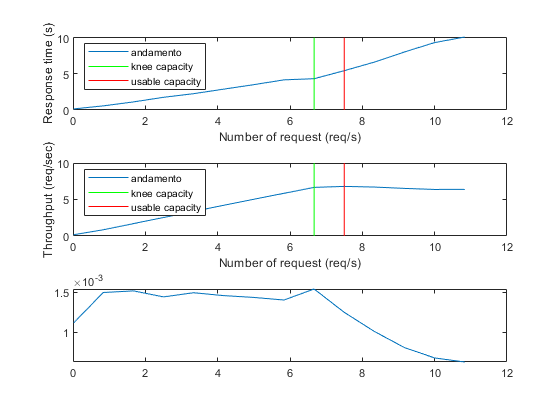

clear
load = (0:50:650)./60;
load(1) = 1/60;
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity medium\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity medium\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
power = throughput./response_time;
subplot(3,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 10000].*0.001,'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 10000].*0.001,'Color','red');
legend('andamento','knee capacity','usable capacity','Location','northwest')
subplot(3,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 10],'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 10],'Color','red');
legend('andamento','knee capacity','usable capacity','Location','northwest')
subplot(3,1,3);
plot(load, power)
saveas(gcf,'capacity_medium','png');

clf

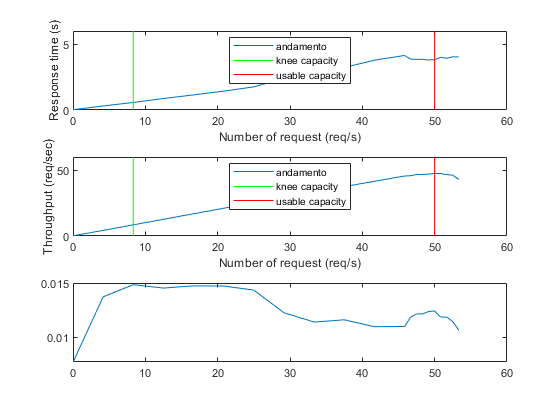

clear
load1 = (0:250:2750)./60;
load2 = (2800:50:3200)./60;
load1(1) = 1/60;
load = cat(2, load1, load2);
response_time = zeros;
throughput = zeros;
matfiles = dir(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity small\summary reports', '*.csv'));
for i = 1 : length(matfiles)
    fileID = fopen(fullfile('C:\Users\Davide\Documents\Università\IE\Homework-IE-18-19\3\design\risultati traccia 2\capacity small\summary reports', matfiles(i).name));
    C = textscan(fileID,'%q %q %q %q %q %q %q %q %q %q %q %q %q','Delimiter',',');
    response_time(i) = str2double(C{3}{4});
    throughput(i) = str2double(strrep(C{8}{4},',','.'));
    fclose(fileID);
end
power = throughput./response_time;
subplot(3,1,1);
plot(load, response_time.*.001)
xlabel('Number of request (req/s)')
ylabel('Response time (s)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 6000].*0.001,'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 6000].*0.001,'Color','red');
legend('andamento','knee capacity','usable capacity','Location','north')
subplot(3,1,2);
plot(load, throughput)
xlabel('Number of request (req/s)')
ylabel('Throughput (req/sec)')
line([load(power==max(power)).*60 load(power==max(power)).*60]./60, [0 60],'Color','green');
line([load(throughput==max(throughput)).*60 load(throughput==max(throughput)).*60]./60, [0 60],'Color','red');
legend('andamento','knee capacity','usable capacity','Location','north')
subplot(3,1,3);
plot(load, power)
saveas(gcf,'capacity_small','png');

clf